# KPP evolution on a honeycomb

Evolves a solution to the KPP equation $u_t = \mu \triangle u + u(1-u)$ on a honeycomb graph. This 

Phi = hexOfHexes("cellsPerSide",4,"nx",32);

## Define and plot the initial conditions 

Define the cubic nonlinear Schrodinger time equation on Phi.s

nspot=53;
spot=round(Phi.nx(nspot)/2);
X1=Phi.Edges.x1{nspot}(spot);
X2=Phi.Edges.x2{nspot}(spot);
f0 = @(x1,x2)exp(-(x1-X1).^2-(x2-X2).^2)/2;
u0 = Phi.applyGraphicalFunction(f0);

## Function Definition and Time evolution


$$f(t,u) = \mu \triangle u + F(t,u)$$


mu = 0.1; 
F =@(t,z) z.*(1-z);
tFinal = 12;
t=0:0.5:tFinal; 
absTol=1e-6;
relTol = 1e-4;
[t,u] = Phi.qgde15s(mu,F,t,u0,'AbsTol',absTol,'RelTol',relTol);

## Plotting the solution

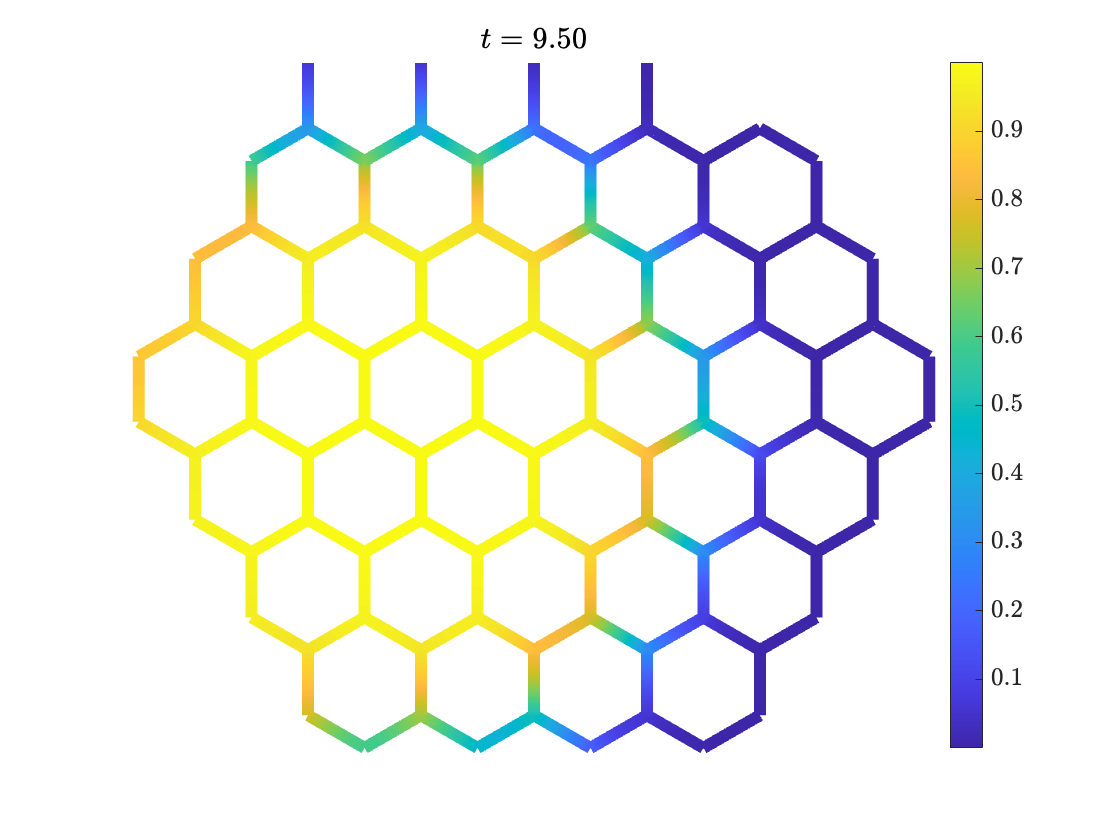

Phi.animatePDESolution2Dcolor(u,t);